### **一. 刚体位置和姿态的数学描述**

- 刚体：如果系统中任意两点的距离保持不变，那么这个系统可以称为刚体。这个定义的含义是：当刚体受力时不会发生变形。理想的刚体实际上并不存在，它是工程上为了突出主要矛盾而做出的近似和抽象。在机器人学中，将机械臂的一部分视作刚体，通常是适用和满足需求的。

- 刚体的位姿描述：我们在刚体上附着一个与刚体固联的坐标系，坐标系的原点代表刚体的位置，坐标系相对基坐标系的姿态作为刚体的姿态。因此，刚体位置的数学描述就是基坐标系中点的坐标，刚体的姿态描述就刚体坐标系相对于基坐标系的转动。

- 坐标系的三个轴的单位矢量分别为：$\vec{e}_x$,$\vec{e}_y$和$\vec{e}_z
$，则空间中的一个点$P$可以用原点$O$到$P
$的矢量$\vec{OP}$表示，即$\vec{OP} = P_x\vec{e_x} + P_y\vec{e_y} + P_z\vec{e_z}$，也可以写成：$\vec{OP} =  \left[\begin{array}{ccc}
\vec{e_x}& \vec{e_y}& \vec{e_z} 
\end{array}\right]
\left[\begin{array}{c}
P_x \\ P_y\\ P_z
\end{array}\right]$。我们称向量$P=\left[\begin{array}{c}
P_x \\ P_y\\ P_z
\end{array}\right]$为点$P$在坐标系下的坐标。

%
ex = [1 0 0]';
ey = [0 1 0]';
ez = [0 0 1]';

P = 1*ex +2*ey + 0*ez

P =      1
     2
     0


V = [0 0 1]'

V =      0
     0
     1


R = angvec2r(pi/6, V)

R =     0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


P1 = inv(R)*P 

P1 =     1.8660
    1.2321
         0


figure
trplot(R, 'frame', '1', 'color', 'r');
hold

已锁定最新绘图


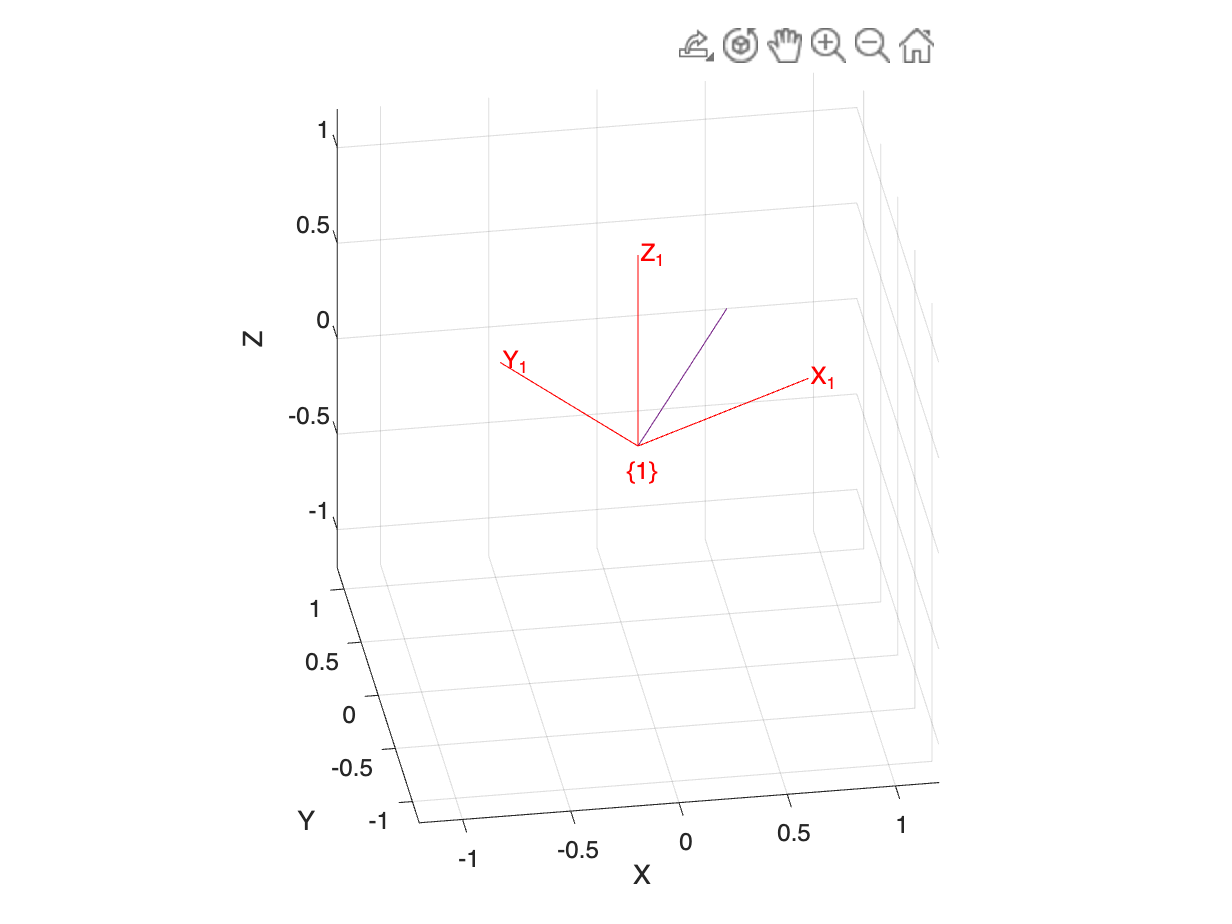

arrow3([0 0],[1,2])

#### **二. 坐标变换矩阵 **

#### **1. 基础坐标变换矩阵**

坐标系$\{0\}$绕某个坐标轴（$x$、$y$或$z$）旋转$\theta$角后得到新坐标系$\{1\}$。${^0}P$、${^1}P$分别是定点P在坐标系$\{0\}$、坐标系$\{1\}$中的坐标。因为二者表示的是同一点，但由于坐标基不同，所以坐标${^0}P$、${^1}P$之间的变换关系为：${^0}P={^0_1}R {^1}P$。

此时，${^0_1}R$可以简写成$R_x(\theta)$、$R_y(\theta)$或$R_z(\theta)$。他们称为基础坐标变换矩阵，其具体形式如下：

$R_{x}(\theta)=\left[\begin{array}{ccc}
1 & 0 & 0 \\
0 & \cos \theta & -\sin \theta \\
0 & \sin \theta & \cos \theta
\end{array}\right]$, 

$R_{y}(\theta)=\left[\begin{array}{ccc}
\cos \theta & 0 & \sin \theta \\
0 & 1 & 0 \\
-\sin \theta & 0 & \cos \theta
\end{array}\right]$, 

$R_{z}(\theta)=\left[\begin{array}{ccc}
\cos \theta & -\sin \theta & 0 \\
\sin \theta & \cos \theta & 0 \\
0 & 0 & 1
\end{array}\right]$。

% 坐标系{0}
R0 = eye(3);
P_0 = [0,0,0]';
P = [1,2,3]';


1) 绕$x$轴旋转30度

Rx = rotx(30,'deg')

Rx =     1.0000         0         0
         0    0.8660   -0.5000
         0    0.5000    0.8660


Px = Rx*P

Px =     1.0000
    0.2321
    3.5981


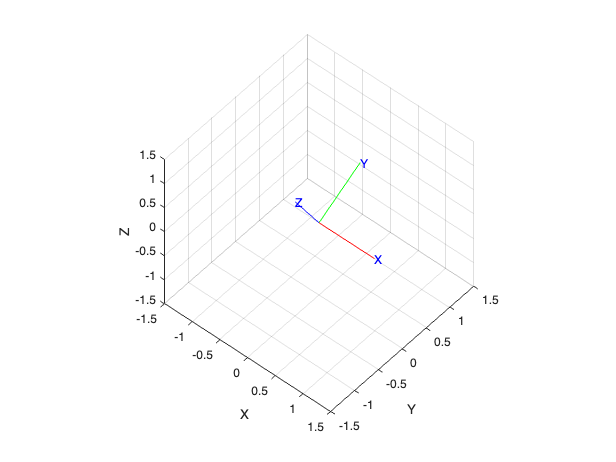

figure;view([40.66 48.80]); tranimate(R0,Rx,'rgb');

2) 绕$y$轴旋转45度

Ry = roty(45,'deg')

Ry =     0.7071         0    0.7071
         0    1.0000         0
   -0.7071         0    0.7071


Py = Ry*P

Py =     2.8284
    2.0000
    1.4142


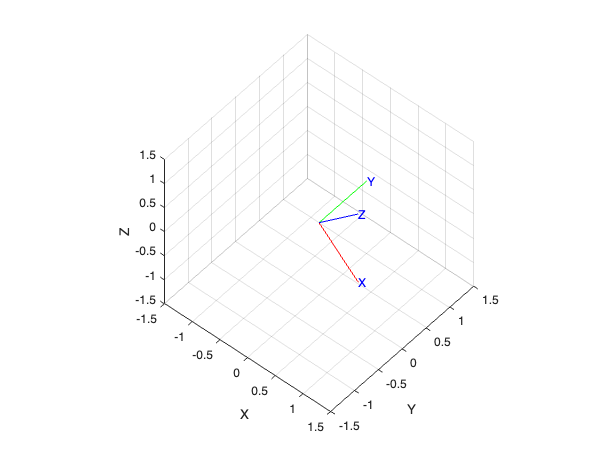

figure;view([40.66 48.80]);tranimate(R0,Ry,'rgb');

3）绕$z$轴旋转60度

Rz = rotz(60,'deg')

Rz =     0.5000   -0.8660         0
    0.8660    0.5000         0
         0         0    1.0000


Pz = Rz*P

Pz =    -1.2321
    1.8660
    3.0000


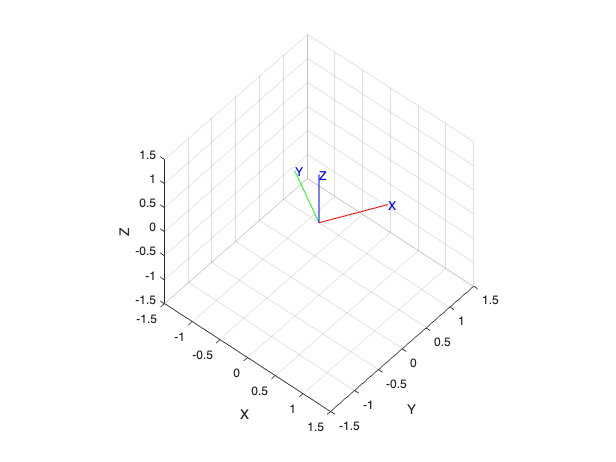

figure;view([40.66 48.80]); tranimate(R0,Rz,'rgb');

####  2. 坐标变换矩阵的复合形式-绕中间轴

1) 坐标系$\{0\}$绕其$z_{0}$轴旋转$\theta_{z}$得到坐标系$\{1\}$

因此：${^0_1}R =R_{z_{0}}(\theta_{z})$

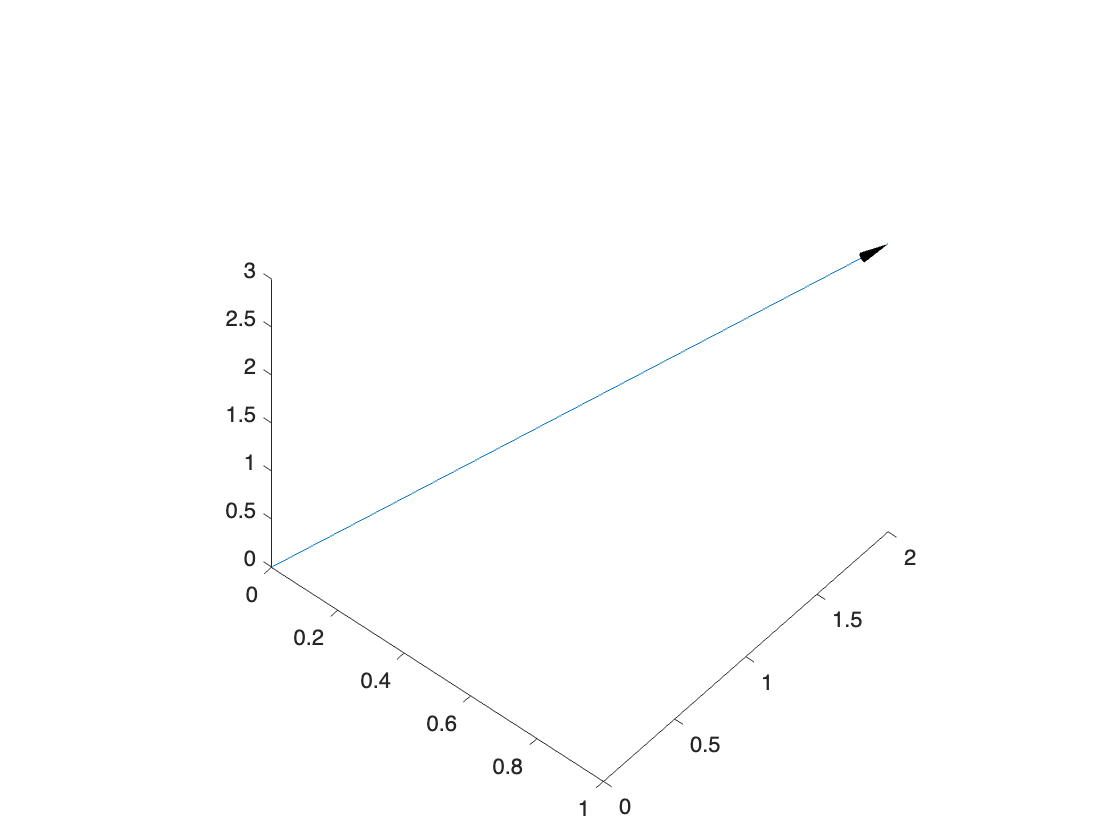

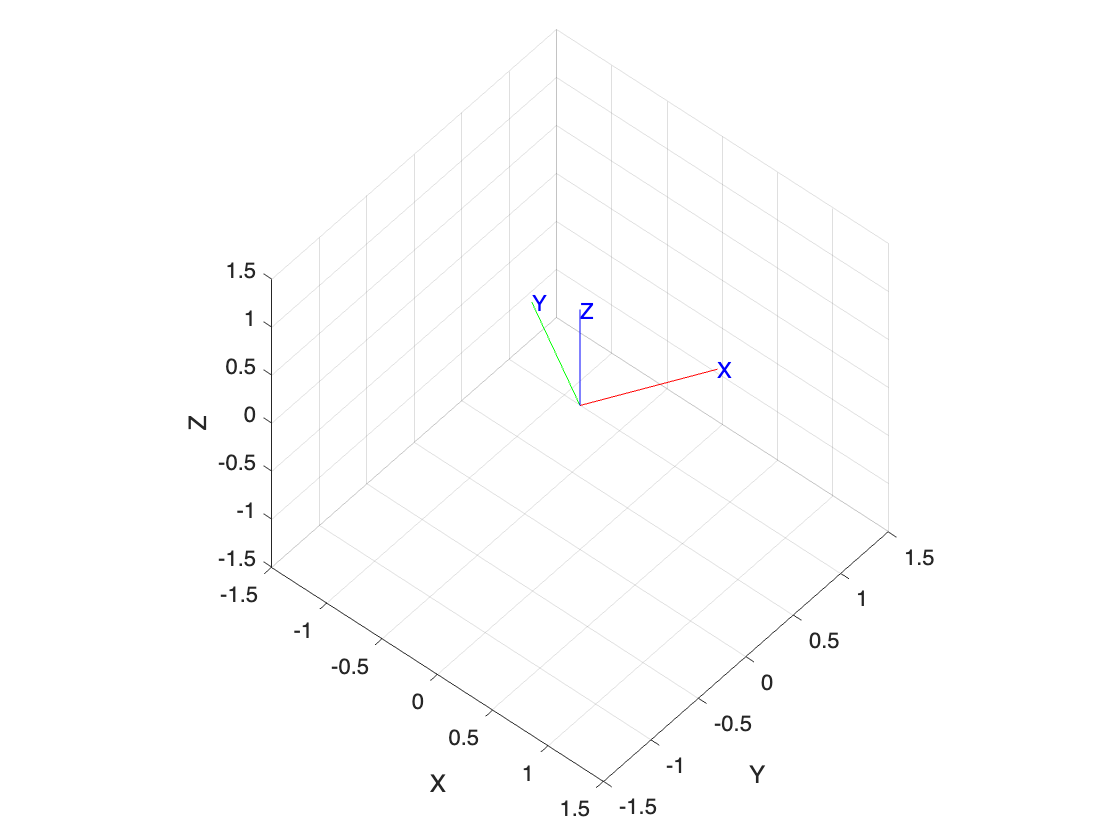

R01 = Rz;
 figure;arrow3(P_0', P');
 view([40.66 48.80]); tranimate(R0,R01,'rgb') 

2) 坐标系$\{1\}$绕其$y_{1}$轴旋转$\theta_{y}$得到坐标系$\{2\}$

因此：${^1_2}R = R_{y_{1}}(\theta_{y})
$，进而得到：${^0_2}R 
={^0_1}R{^1_2}R 
=R_{z_0}(\theta_{z}) R_{y_1}(\theta_{y}) 
$

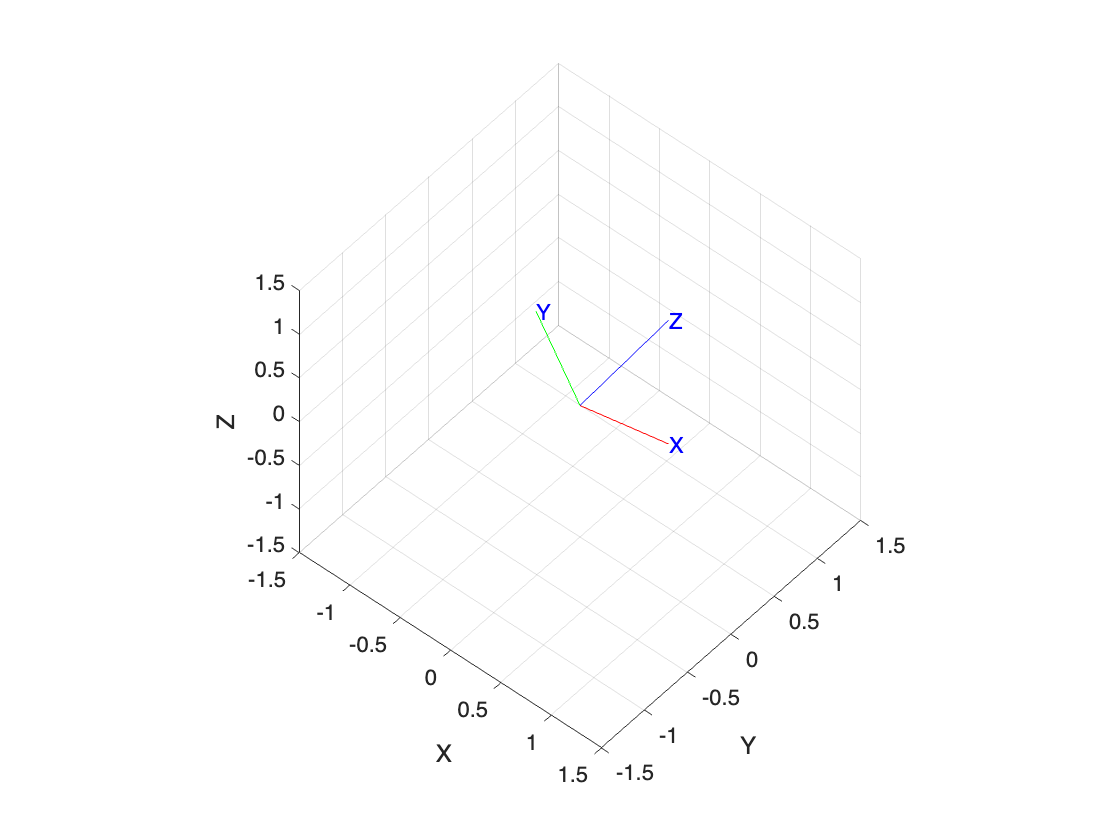

R12 = Ry;
R02 = R01*R12;
figure;view([40.66 48.80]); tranimate(R01,R02,'rgb')

3) 坐标系$\{2\}$绕$x_{2}$轴旋转$\theta_x$得到坐标系$\{3\}$

因此：${^2_3}R = R_{x}(\theta_{x})
$，进而得到${^0_3}R 
= {^0_1}R{^1_2}R{^2_3}R
= R_{z_0}(\theta_{z})R_{y_1}(\theta_{y})R_{x_2}(\theta_x) 
$，

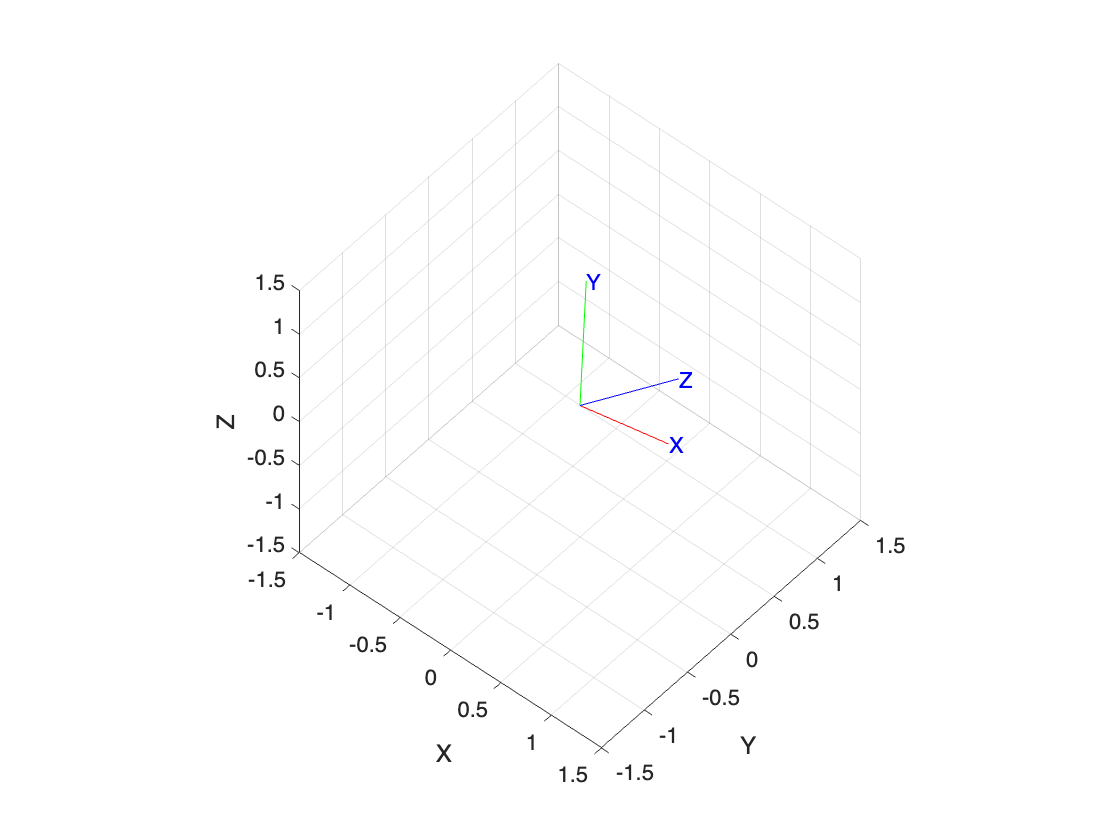

R23 = Rx;
R03= R01*R12*R23;
figure;view([40.66 48.80]); tranimate(R02,R03,'rgb')

也可以先展开得到坐标变换矩阵的表达式，即：


$${^0_3}R=
R_{z_{0}} R_{y_{1}} R_{x_{2}}
\\=\left[\begin{array}{ccc}
\cos (\theta_z) & -\sin (\theta_z) & 0 \\
\sin (\theta_z) & \cos (\theta_z) & 0 \\
0 & 0 & 1
\end{array}\right]\left[\begin{array}{ccc}
\cos (  {\theta_y}) & 0 & \sin (  {\theta_y}) \\
0 & 1 & 0 \\
-\sin (  {\theta_y}) & 0 & \cos (  {\theta_y})
\end{array}\right]\left[\begin{array}{ccc}
1 & 0 & 0 \\
0 & \cos (  {\theta_x}) & -\sin (  {\theta_x}) \\
0 & \sin (  {\theta_x}) & \cos (  {\theta_x})
\end{array}\right]

\\=\left[\begin{array}{ccc}
\cos (\theta_z) \cos (  { \theta_y}) & \cos (\theta_z) \sin (  { \theta_y}) \sin (  { \theta_x })-\sin (\theta_z) \cos (  { \theta_x }) & \cos (\theta_z) \sin (  { \theta_y }) \cos (  { \theta_x })+\sin (\theta_z) \sin (  { \theta_x }) \\
\sin (\theta_z) \cos (  { \theta_y }) & \sin (\theta_z) \sin (  { \theta_y }) \sin (  { \theta_x })+\cos (\theta_z) \cos (  { \theta_x }) & \sin (\theta_z) \sin (  { \theta_y }) \cos (  { \theta_x })-\cos (\theta_z) \sin (  { \theta_x }) \\
-\sin (  { \theta_y }) & \cos (  { \theta_y }) \sin (  { \theta_x }) & \cos (  { \theta_y }) \cos (  { \theta_x })
\end{array}\right]$$


% 同学们可以尝试自己写这个3X3的矩阵。
% 也可以比较一下两种方法的计算效率。

#### 3. 坐标变换矩阵-中间轴-欧拉角

% 复合旋转
R = rotz(0.1) * roty(0.2) * rotz(0.3)

R =     0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


gamma_R = tr2eul(R)

gamma1 =     0.1000    0.2000    0.3000



% 欧拉角函数，默认ZYZ次序
R0 = eul2r(0.1, 0.2, 0.3)

R0 =     0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


gamma0 = tr2eul(R0)

gamma0 =     0.1000    0.2000    0.3000


%比较两个旋转矩阵和欧拉角

#### 4. 坐标变化矩阵-固定轴-欧拉角

% 滚动-俯仰-偏航（Roll-Pitch-Yaw），默认ZYX旋转
R = rpy2r(0.1, 0.2, 0.3)

R =     0.9363   -0.2751    0.2184
    0.2896    0.9564   -0.0370
   -0.1987    0.0978    0.9752



% 获得欧拉角，默认ZYX次序旋转
gamma = tr2rpy(R)

gamma =     0.1000    0.2000    0.3000



% xyz次序的欧拉角
R1 = rpy2r(0.1, 0.2, 0.3, 'xyz')

R1 =     0.9752   -0.0978    0.1987
    0.1538    0.9447   -0.2896
   -0.1593    0.3130    0.9363


gamma1 = tr2rpy(R1, 'xyz')

gamma1 =     0.1000    0.2000    0.3000


gamma2 = tr2rpy(R1)

gamma2 =     0.3226    0.1600    0.1564


% note gamma1 and gamma2!

% xyz次序欧拉角的手动计算
% 注意这里三个矩阵Rz在最左边
Rh = Rz * Ry * Rx;
gamm3 = 180*tr2rpy(Rh)/pi

gamm3 =    30.0000   45.0000   60.0000


#### 5. 齐次坐标变换矩阵（Homogeneous Transformation Matrix）

% 2D examples
% 
plotvol([0 5 0 5]);

T1 = transl2(1, 2) * trot2(30, 'deg')

T1 =     0.8660   -0.5000    1.0000
    0.5000    0.8660    2.0000
         0         0    1.0000


trplot2(T1, 'frame', '1', 'color', 'b')

T2 = transl2(2, 1)

T2 =      1     0     2
     0     1     1
     0     0     1


trplot2(T2, 'frame', '2', 'color', 'r');

T3 = T1*T2

T3 =     0.8660   -0.5000    2.2321
    0.5000    0.8660    3.8660
         0         0    1.0000


trplot2(T3, 'frame', '3', 'color', 'g');

T4 = T2*T1

T4 =     0.8660   -0.5000    3.0000
    0.5000    0.8660    3.0000
         0         0    1.0000


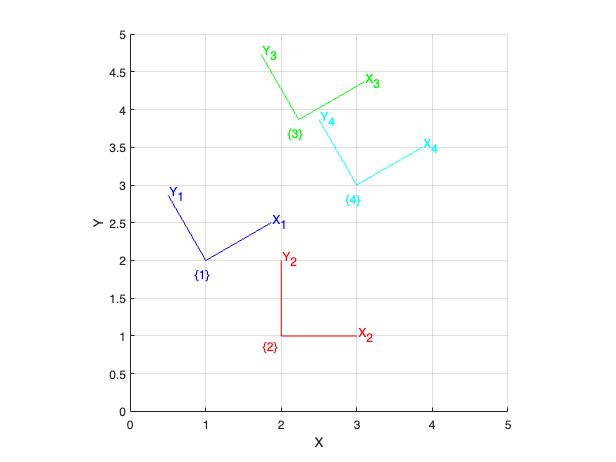

trplot2(T4, 'frame', '4', 'color', 'c');

% 可以比较容易看出坐标系{3}和坐标系{4}的位置不同

% 3-Dimensions Homogeneous Transformation Matrix
% 平移
T1 = transl(3, 2, 1)

T1 =      1     0     0     3
     0     1     0     2
     0     0     1     1
     0     0     0     1


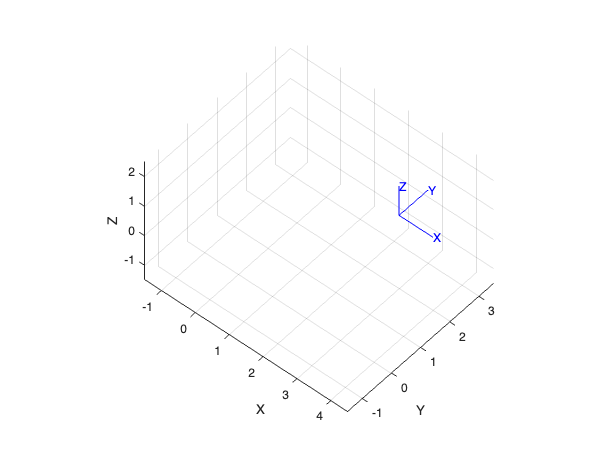

figure;view([40.66 48.80]); tranimate(T1)


% 绕坐标系原点旋转
T2 = trotx(pi/6) 

T2 =     1.0000         0         0         0
         0    0.8660   -0.5000         0
         0    0.5000    0.8660         0
         0         0         0    1.0000


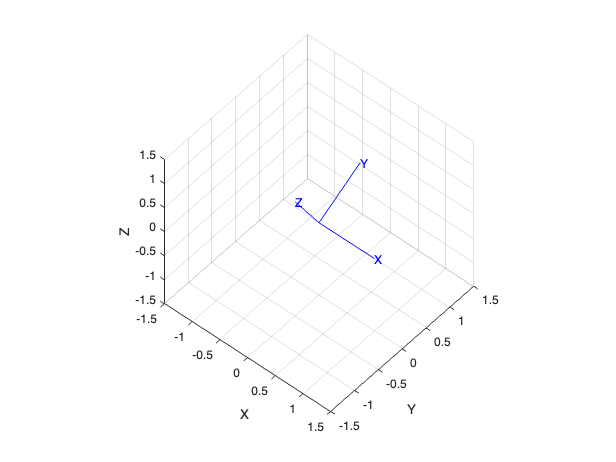

figure;view([40.66 48.80]); tranimate(T2)


% 合成1
CT1 = T1*T2

CT1 =     1.0000         0         0    3.0000
         0    0.8660   -0.5000    2.0000
         0    0.5000    0.8660    1.0000
         0         0         0    1.0000


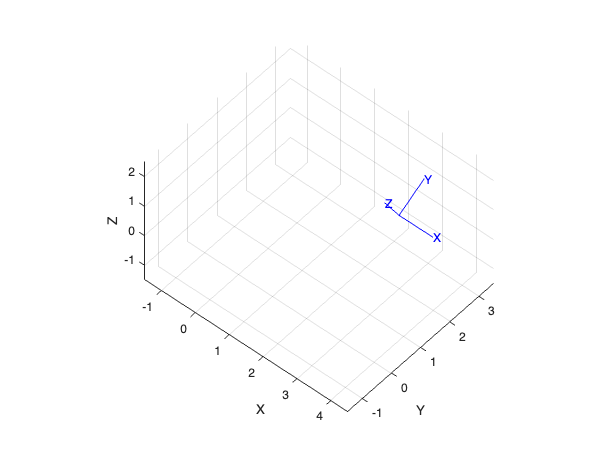

figure;view([40.66 48.80]); tranimate(CT1)


% 合成2
CT2 = T2*T1

CT2 =     1.0000         0         0    3.0000
         0    0.8660   -0.5000    1.2321
         0    0.5000    0.8660    1.8660
         0         0         0    1.0000


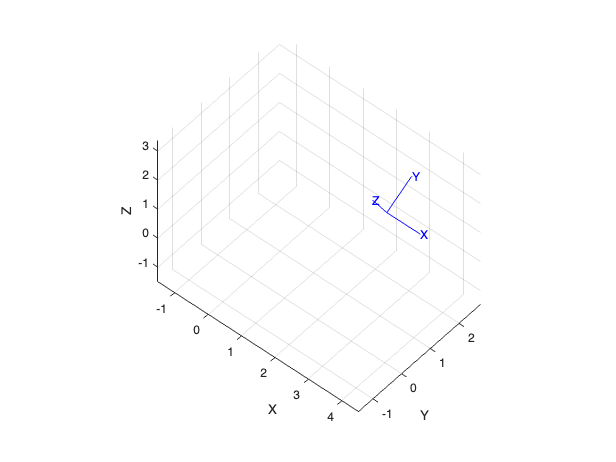

figure;view([40.66 48.80]); tranimate(CT2)

% 用肉眼不太容易看出CT1和CT2有区别
% 但数据显示更容易看出来。
R1 = t2r(CT1)

R1 =     1.0000         0         0
         0    0.8660   -0.5000
         0    0.5000    0.8660


P1 = transl(CT1)

P1 =      3
     2
     1



R2 = t2r(CT2)

R2 =     1.0000         0         0
         0    0.8660   -0.5000
         0    0.5000    0.8660


P2 = transl(CT2)

P2 =     3.0000
    1.2321
    1.8660


这是因为：$\left[\begin{array}{ccc}
I & P  \\
0 & 1 \\
\end{array}\right]
\left[\begin{array}{ccc}
R & 0  \\
0 & 1 \\
\end{array}\right]
=
\left[\begin{array}{ccc}
R & P  \\
0 & 1 \\
\end{array}\right]$，而$\left[\begin{array}{ccc}
R & 0  \\
0 & 1 \\
\end{array}\right]
\left[\begin{array}{ccc}
I & P  \\
0 & 1 \\
\end{array}\right]
=
\left[\begin{array}{ccc}
R & RP  \\
0 & 1 \\
\end{array}\right]$，

所以保险起见，我们认为$\left[\begin{array}{ccc}
R & P  \\
0 & 1 \\
\end{array}\right]$是与“先平移再旋转”相对应。而先旋转后平移时是按着$RP$的方向平移的。

注：而在DH方法中，“先沿某轴平移再绕同一个轴旋转”和"先绕某轴旋转再沿同一个平移“的结果是一样的，因此不用特别说明一定是先平移再旋转。

P3 = R1*P1

P3 =     3.0000
    1.2321
    1.8660


% P3 = P2?